x = readmatrix('parameter_estimation2.csv' );

phi = x(:,3);

maxX = zeros(33,1);
L = 682; %No. eo elements in one window 
Fs = 85; % sampling frequency
for i = 1:33
   y = fft(phi(681*i:681*(i+1)));
   P2 = abs(y/L);
   P1 = P2(1:L/2+1);
   P1(1) = 0; % make dc component zero 
   P1(2:end-1) = 2*P1(2:end-1);
   f = Fs*(0:(L/2))/L;
   plot(f,P1) 
   hold on;
   title('Single-Sided Amplitude Spectrum of X(t)')
   xlabel('f (Hz)')
   ylabel('|P1(f)|')
   maxF = max(P1);  % Find max value over all elements.
   indexOfFirstMax = find(P1 == maxF, 1, 'first');  % Get first element that is the max.
   % Get the x value(frequency) at that index
   maxX(i) = f(indexOfFirstMax);
end
hold off

plot(maxX)

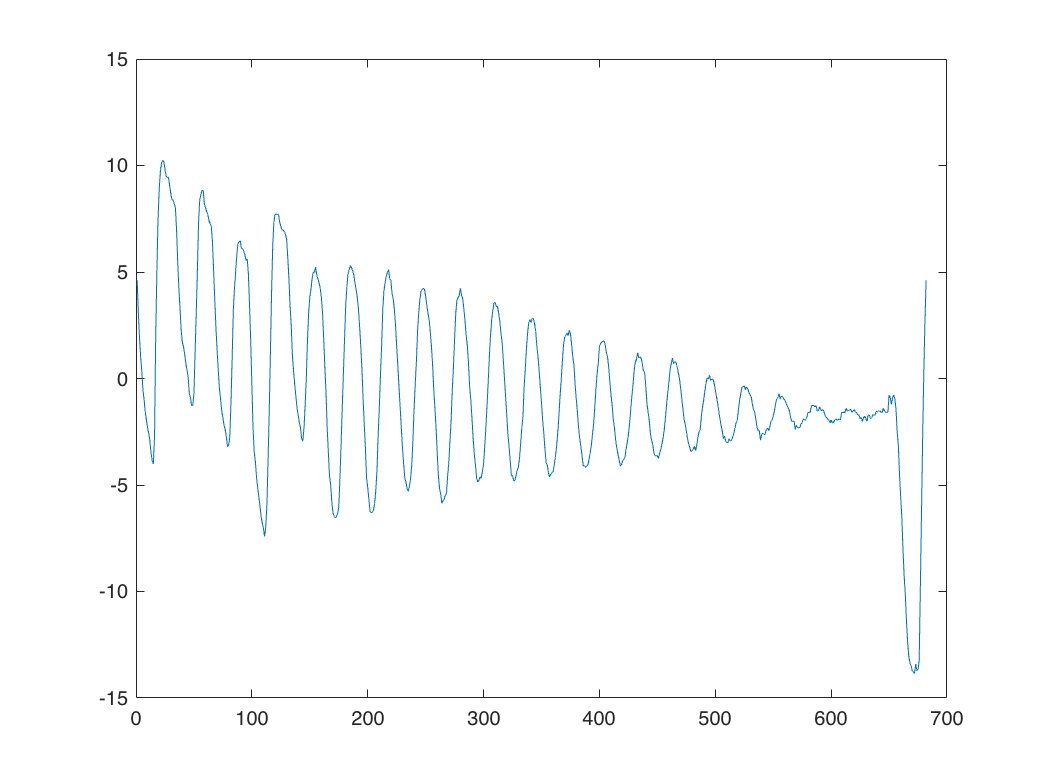

wd = 2.7419; %damped frequency 
data = x(:,2);
plot( data(681*24:681*25 ))

coeff_of_damping = 0.000279

coeff_of_damping = 2.7900e-04

wn = 17.2688

wn = 17.2688

l = 0.0328

l = 0.0328

%2,4,8 ,13,16,22,24,26,32